# Práctica 2

## **Ejercicio 1.**

**    a) **Representa y compara los diagramas de magnitud de la respuesta en frecuencia de filtros FIR de orden 50 usando las siguientes ventanas. Emplea las mismas especificaciones en los cuatro casos.

   - Triangular

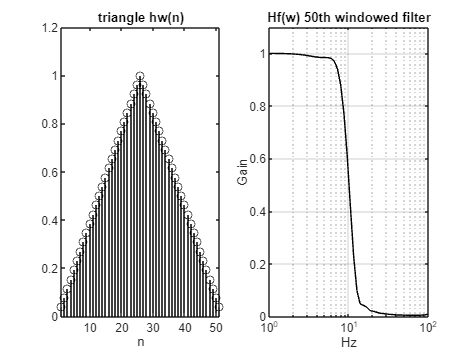

fs = 130;
fc = 10/(fs/2);
N=50;
hw = triang(N+1);
numd = fir1(N,fc,hw);
dend = 1;

figure (1);
subplot(1,2,1)
stem(hw,'k');
axis([1 51 0 1.05]);
title('triangle hw(n)');
xlabel('n');

subplot(1,2,2)
f=logspace(0,2);
G=freqz(numd,dend,f,fs);
semilogx(f,abs(G),'k');
grid;
axis([1 100 0 1.1]);
ylabel('Gain'); xlabel('Hz'); title('Hf(w) 50th windowed filter');

    - Hanning

fs = 130;
fc = 10/(fs/2);
N=50;
hw = hanning(N+1);
numd = fir1(N,fc,hw);
dend = [1];

figure (2);
subplot(1,2,1)
stem(hw,'k');
axis([1 51 0 1.2]);
title('Hanning hw(n)');
xlabel('n');

subplot(1,2,2)
f=logspace(0,2);
G=freqz(numd,dend,f,fs);
semilogx(f,abs(G),'k');
grid;
axis([1 100 0 1.1]);
ylabel('Gain'); xlabel('Hz'); title('Hf(w) 50th windowed filter');

    - Blackman

fs = 130;
fc = 10/(fs/2);
N=50;
hw = blackman(N+1);
numd = fir1(N,fc,hw);
dend = [1];

figure (3);
subplot(1,2,1)
stem(hw,'k');
axis([1 51 0 1.2]);
title('Blackman hw(n)');
xlabel('n');

subplot(1,2,2)
f=logspace(0,2);
G=freqz(numd,dend,f,fs);
semilogx(f,abs(G),'k');
grid;
axis([1 100 0 1.1]);
ylabel('Gain'); xlabel('Hz'); title('Hf(w) 50th windowed filter');

- Chebyshev

fs = 130;
fc = 10/(fs/2);
N=50;
hw = chebwin(N+1);
numd = fir1(N,fc,hw);
dend = [1];

figure (4);
subplot(1,2,1)
stem(hw,'k');
axis([1 51 0 1.2]);
title('Chebyshev hw(n)');
xlabel('n');

subplot(1,2,2)
f=logspace(0,2);
G=freqz(numd,dend,f,fs);
semilogx(f,abs(G),'k');
grid;
axis([1 100 0 1.1]);
ylabel('Gain'); xlabel('Hz'); title('Hf(w) 50th windowed filter');

**    b)** Representa y compara los diagramas de magnitud de la respuesta en frecuencia de los siguientes filtros FIR de orden 50. Emplea las mismas especificaciones en los dos casos. Analiza las gráficas.

    - Parks-McLelland

fs = 130;
fc = 10/(fs/2);
N = 50;

F = [0 fc fc+0.05 1];
A=[1 1 0 0];
numd = remez(N,F,A);
dend = [1];


figure (5);
subplot(1,2,1)
stem(numd); axis([1 51 -0.05 0.2]); 
title('h(n)'); xlabel('n');

subplot(1,2,2);
f = logspace(0,2,200);
G = freqz(numd,dend,f,fs);
semilogx(f, abs(G));
axis([1 100 0 1.1]); grid;
xlabel('Hz'); title('50th Parks-MsClelland filter Hf(w)');

 - Least-Squares Error 

fs = 130;
fc = 10/(fs/2);

N = 50;
Rp = 0.5;

F = [0 fc fc+0.05 1];
A=[1 1 0 0];
numd = firls(N,F,A);
dend = [1];


figure (6);
subplot(1,2,1)
stem(numd); axis([1 51 -0.05 0.2]); 
title('h(n)'); xlabel('n');

subplot(1,2,2);
f = logspace(0,2,200);
G = freqz(numd,dend,f,fs);
semilogx(f, abs(G));
axis([1 100 0 1.1]); grid;
xlabel('Hz'); title('50th least-squares error filter Hf(w)');

**Ejercicio 2. **Genera 5 segundos de una onda cuadrada de frecuencia 800 Hz, pero representa sólo 0.005 segundos de la misma. Diseña un filtro FIR Hamming para extraer el armónico fundamental. Oye y representa tanto la señal original como la resultante. Nota: emplea el comando “filter()” para aplicar el filtro diseñado. Analiza los resultados.

fs = 2000;
fc = 10/(fs/2);
fu = 800;
wu = 2*pi*fu;
tiv = 1/fs;
t=0:tiv:(0.005-tiv);
u=square(wu*t);

N = 50;
hw = hamming(N+1);
numd = fir1(N,fc,hw);
dend = [1];

y = filter(numd,dend,u);
plot(t,u); hold on
plot(t,y)
sound(y,fs);

a

clear all;
close allh
N = 100;
H =[ones(N,1);zeros(256-N,1);zeros(256-N,1);ones(N,1)]'

H =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


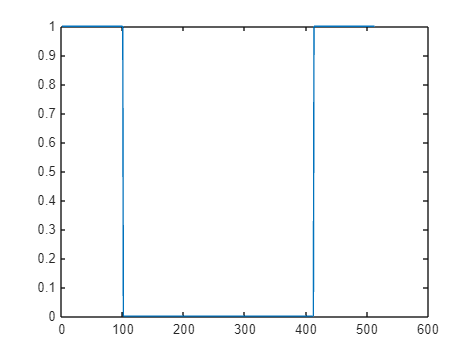

hold off
plot(H)